# Modelagem de um sistema dinâmico

## Boas Praticas

clear all;
close all;
clc;

## Lendo os dados do sistema dinâmico real

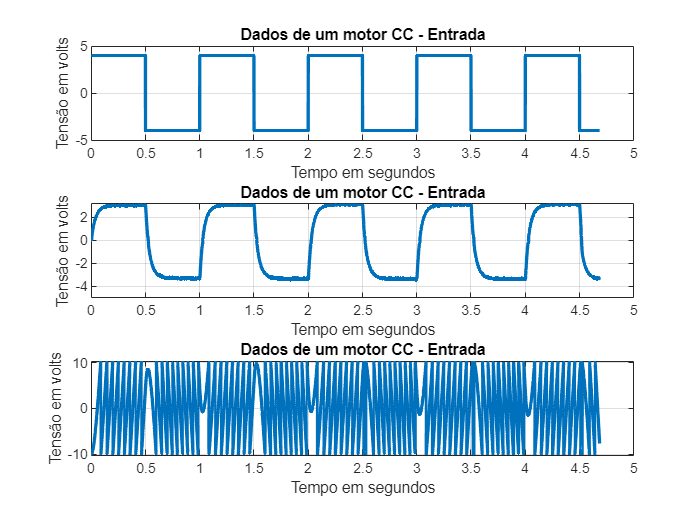

%%% Lendo os dados do arquivo txt

LerDados

%%% Informações do sistema de aquisição

T = 1e-3;                   %%% Taxa de amostragem
N = length(Entrada);        %%% Número de pontos

%%% Criando o vetor tempo

tempo = linspace(0, N*T, N);

%%% Visualizando os dados

figure(1)

subplot(3,1,1)              %%% Primeiro gráfico

plot(tempo, Entrada, 'LineWidth',2)
title('Dados de um motor CC - Entrada')
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
grid

subplot(3,1,2)              %%% Segundo gráfico

plot(tempo, Omega, 'LineWidth',2)
title('Dados de um motor CC - Entrada')
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
grid

subplot(3,1,3)              %%% Terceiro gráfico

plot(tempo, Posicao, 'LineWidth',2)
title('Dados de um motor CC - Entrada')
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
grid

## Criando um modelo em Laplace

O sinal de entrada $U\left(s\right)$ foi aplicado a um sistema cuja função de transferência gerou o sinal $\Omega \left(s\right)$. Logo a relação entre entrada e saída é dada pela função de transferêcia:

$\frac{\Omega \left(s\right)}{U\left(s\right)}=\frac{K_m }{s+p_m }$. Neste caso supomos ser de primeira ordem pelo aspecto geral do sinal **Rotação**

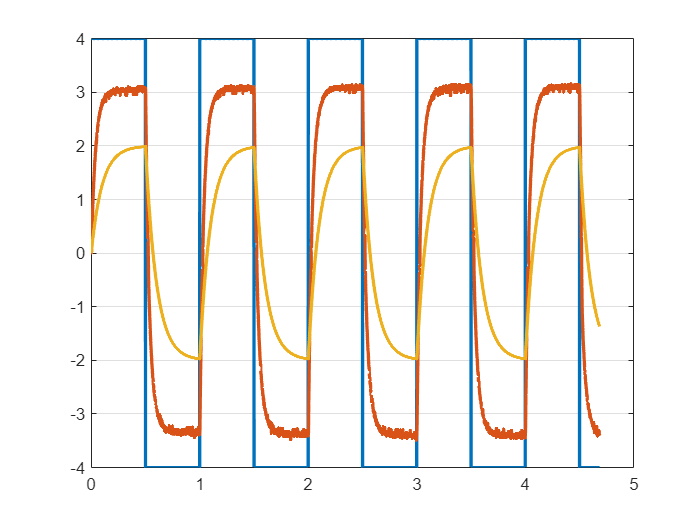

Km = 5;   %%% Ganho inicial
pm = 10;  %%% Polo inicial

%%% Função de tranferência => Modelo em Laplace

Gp = tf(Km,[1 pm]);

%%% Simulando o Modelo com a mesma entrada do sistema real

ym = lsim(Gp, Entrada, tempo);

%%% Comparando os dados simulados com os dados reais

figure(3)

plot(tempo, Entrada, tempo, Omega, tempo, ym, 'LineWidth', 2);
grid;

## Ajustando o modelo em Laplace - Aprendizado

x0 = [1 1];  % Condição inicial Km = 1 e pm = 1

x = fminsearch(@(x)ErroQuadratico(x, Omega, tempo, Entrada), x0);

## Comparando o modelo e dados

%%% Atualizando os valores

Km = x(1)

Km = 22.4732

pm = x(2)

pm = 28.0882

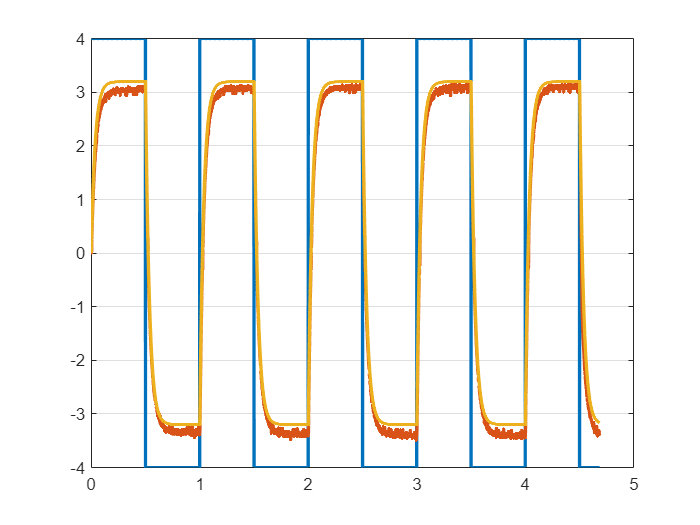


%%% Montagem da função de tranferência

Gp = tf(Km,[1 pm]);

%%% Aplico no modelo a mesma entrada que apliquei no sistema real

ym = lsim(Gp, Entrada, tempo);

%%% Visualizando o resultado

figure(4)

plot(tempo, Entrada, tempo, Omega, tempo, ym, 'LineWidth', 2);
grid;